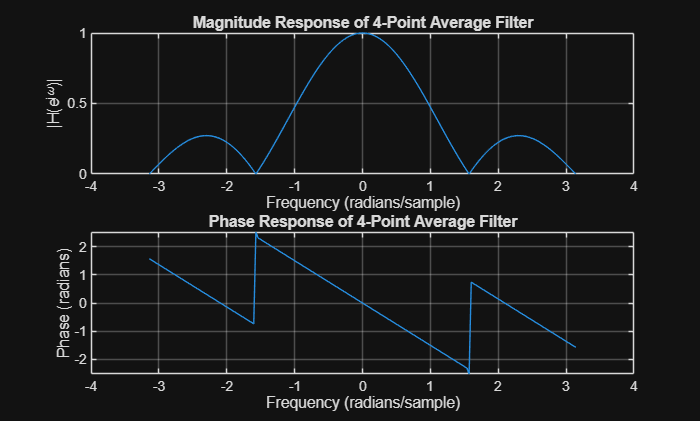

clc; clear; close all;
% Task 1a: 4 point moving filter

K = 4;
bb = ones(1, K) / K;
ww = -pi : (pi/100) : pi; % Frequency range

H = freqz(bb, 1, ww); % Frequency response

figure;
subplot(2,1,1);
plot(ww, abs(H));
grid on;
title('Magnitude Response of 4-Point Average Filter');
xlabel('Frequency (radians/sample)');
ylabel('|H(e^{j\omega})|');

subplot(2,1,2);
plot(ww, angle(H));
grid on;
title('Phase Response of 4-Point Average Filter');
xlabel('Frequency (radians/sample)');
ylabel('Phase (radians)');

## Task 1b: Smoothing Effect

The magnitude response of the 4-point moving average filter shows a low-pass characteristic. Low-frequency components pass through the filter with little attenuation, while high frequency components are significantly reduced. Since rapid variations or noise in signals correspond to high frequencies, their attenuation results in a smoothing effect on the signal.

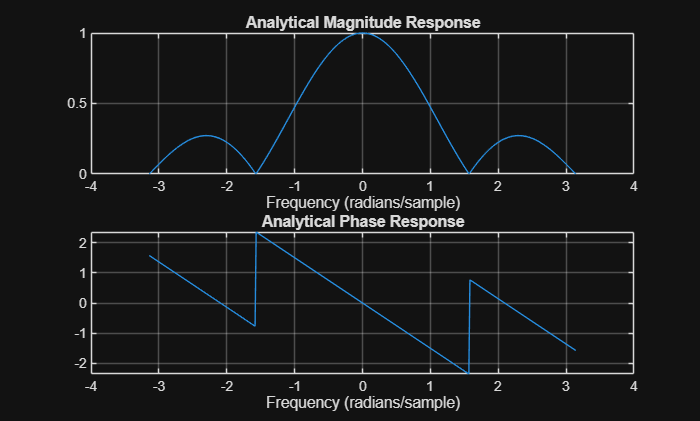

% Task 1c: Analytical implementation
w_analytical = linspace(-pi, pi, 400);

H_analytical = ((2*cos(0.5*w_analytical) + 2*cos(1.5*w_analytical)) / 4) ...
               .* exp(-1j * 1.5 * w_analytical);

mag_H = abs(H_analytical);
phase_H = angle(H_analytical);

figure;
subplot(2,1,1);
plot(w_analytical, mag_H);
title('Analytical Magnitude Response');
grid on;
xlabel('Frequency (radians/sample)');

subplot(2,1,2);
plot(w_analytical, phase_H);
title('Analytical Phase Response');
grid on;
xlabel('Frequency (radians/sample)');

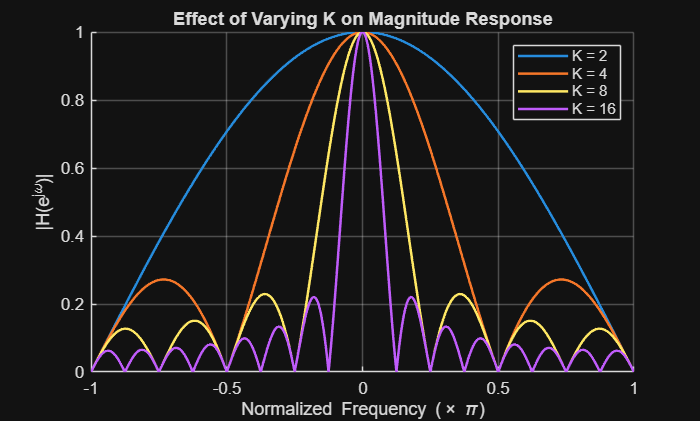

% Task 1d: Effect of differnt K

ww = linspace(-pi, pi, 1000); % Frequency axis
K_values = [2, 4, 8, 16]; %filter lengths

figure;
hold on;

for i = 1:length(K_values)
    K = K_values(i);
    bb = ones(1, K) / K; % Moving filter
    
    H = freqz(bb, 1, ww); %frequency response
    
    plot(ww/pi, abs(H), 'LineWidth', 1.5, ...
        'DisplayName', ['K = ', num2str(K)]);
end

grid on;ghd
title('Effect of Varying K on Magnitude Response');
xlabel('Normalized Frequency (\times \pi)');
ylabel('|H(e^{j\omega})|');
legend;
hold off;

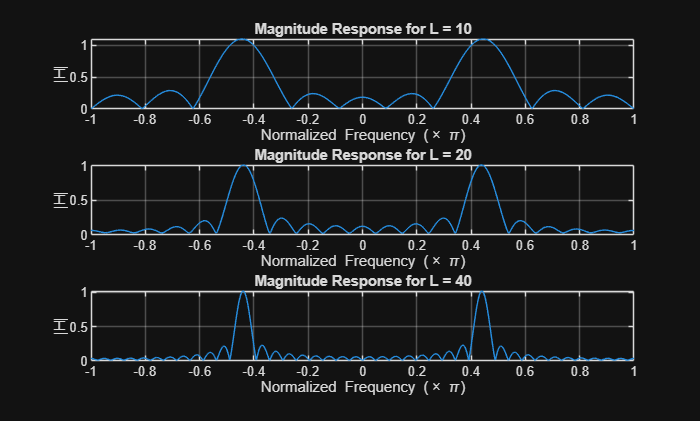

For L = 10, Passband Width = 3.3020 radians
For L = 20, Passband Width = 3.0252 radians
For L = 40, Passband Width = 2.8869 radians


% Task 2 (a & b): Band-pass filter

wc = 0.44 * pi;
L_values = [10, 20, 40];
ww = linspace(-pi, pi, 1000);

figure;
for i = 1:length(L_values)
    L = L_values(i);
    n = 0:L-1;

    hh = (2/L) * cos(wc * n); % Impulse response
    H = freqz(hh, 1, ww);

    subplot(3,1,i);
    plot(ww/pi, abs(H));
    grid on;
    title(['Magnitude Response for L = ', num2str(L)]);
    xlabel('Normalized Frequency (\times \pi)');
    ylabel('|H|');

    % Passband width calculation
    H_max = max(abs(H));
    indices = find(abs(H) >= (H_max / sqrt(2)));
    width = ww(indices(end)) - ww(indices(1));

    fprintf('For L = %d, Passband Width = %.4f radians\n', L, width);
end

% Task 2(c): Filter design
wc = 0.44 * pi;
L = 66; % chosen after testing
n_idx = 0:L-1;
h_bp = (2/L) * cos(wc * n_idx);

ww = linspace(-pi, pi, 1000);
H = freqz(h_bp, 1, ww);
H_max = max(abs(H));

% Check attenuation at unwanted frequencies
[~, idx1] = min(abs(ww - 0.3*pi));
[~, idx2] = min(abs(ww - 0.7*pi));

fprintf('Attenuation at 0.3pi = %.4f\n', abs(H(idx1))/H_max);

Attenuation at 0.3pi = 0.0593


fprintf('Attenuation at 0.7pi = %.4f\n', abs(H(idx2))/H_max);

Attenuation at 0.7pi = 0.0440


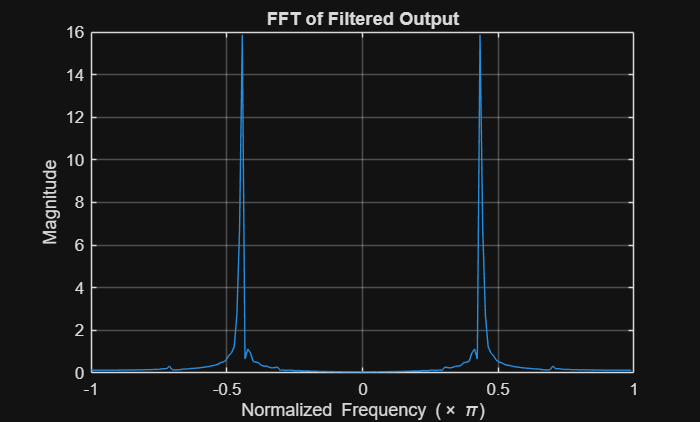

% Task 2d: Testing with input signal
n = 0:200;
x = 10*cos(0.3*pi*n) + 40*cos(0.44*pi*n - pi/3) + 20*cos(0.7*pi*n - pi/4);

y = filter(h_bp, 1, x);

% FFT Analysis
N_fft = length(y);
Y_fft = fftshift(fft(y));

% Frequency axis
f_axis = (-N_fft/2 : N_fft/2-1) * (2/N_fft);

figure;
plot(f_axis, abs(Y_fft)/N_fft);
title('FFT of Filtered Output');
xlabel('Normalized Frequency (\times \pi)');
ylabel('Magnitude');
grid on;

%The FFT of the filtered output shows that the frequency component at
%0.44π is preserved with high magnitude, while the components at 0.3π and 0.7π are significantly attenuated. This confirms that the designed filter effectively behaves as a band-pass filter centered at 0.44π.
%The attenuation of the unwanted frequency components satisfies the required condition of reducing them by at least a factor of 10, indicating that the chosen filter length is appropriate. 
% Overall, the filter successfully isolates the desired frequency while suppressing noise and other undesired components, demonstrating proper band-pass filtering behavior.